nx1 = 0 : 4;
nh1 = 0 : 4;

xg = [2, zeros(1, 4)];
h2 = [0, 2, 5, 4, -1];

yga = xg .^ 2;
yga = [yga, zeros(1, 4)]

yga =      4     0     0     0     0     0     0     0     0


nygb = nx1(1) + nh1(1) : nx1(end) + nh1(end);
ygb = conv(xg, h2);

yg1 = yga + ygb;

ndelta = nx1;
delta = [1, zeros(1, 4)];

hg1 = delta .^ 2;

hparallel = hg1 + h2;

nyg2 = nx1(1) + nh1(1) : nx1(end) + nh1(end);
yg2 = conv(xg, hparallel);

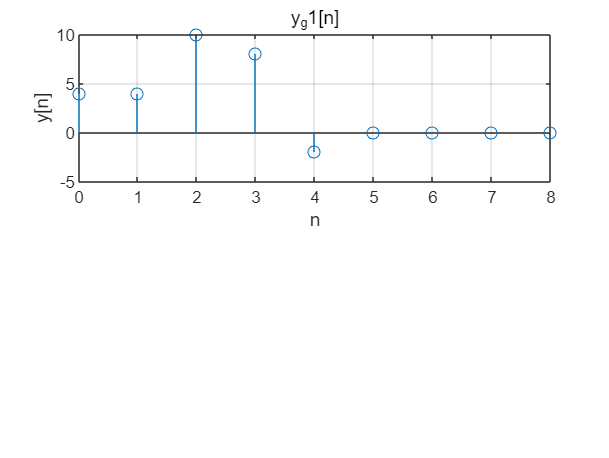

subplot(2, 1, 1);
stem(nygb, yg1);
title("y_g1[n]");
xlabel("n")
ylabel("y[n]");
grid on;

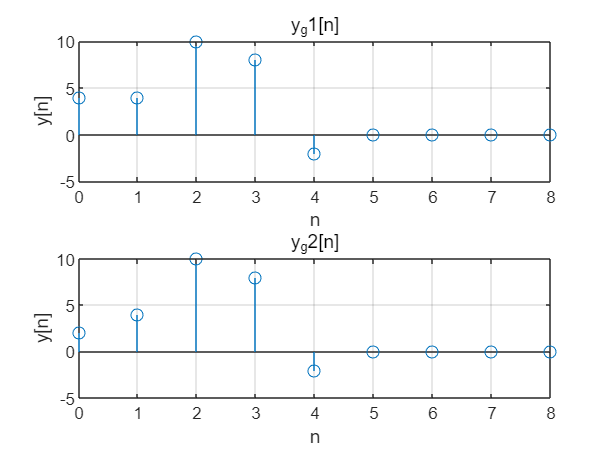

subplot(2, 1, 2);
stem(nyg2, yg2);
title("y_g2[n]");
xlabel("n")
ylabel("y[n]");
grid on;